panel_to_error = 13

panel_to_error = 13

soure_to_ref = 2

soure_to_ref = 2

source_to_panel = 92

source_to_panel = 92

source_to_error = source_to_panel + panel_to_error

source_to_error = 105


fs = 48000

fs = 48000

sound = 343

sound = 343

panel_to_error_samples = panel_to_error * fs / (sound * 100)

panel_to_error_samples = 18.1924

source_to_ref_samples = soure_to_ref * fs / (sound * 100)

source_to_ref_samples = 2.7988

source_to_error_samples = source_to_error * fs / (sound * 100)

source_to_error_samples = 146.9388

load('ir_delay_tests.mat')
error_ir = measurementData(1, 2).ImpulseResponse.Amplitude;
source_ir = measurementData(2, 2).ImpulseResponse.Amplitude;
reverb_ir = measurementData(3, 2).ImpulseResponse.Amplitude;


[error_max, error_idx] = max(error_ir)

error_max = 0.0147

error_idx = 3316

[source_max, source_idx] = max(source_ir)

source_max = 0.0727

source_idx = 3305

[reverb_max, reverb_idx] = max(reverb_ir)

reverb_max = 0.0065

reverb_idx = 3452

error_idx - source_idx

ans = 11

panel_to_error_samples - source_to_ref_samples

ans = 15.3936


reverb_idx - source_idx

ans = 147

source_to_error_samples - source_to_ref_samples

ans = 144.1399

start = source_idx - round(source_to_ref_samples)

start = 3302

cut = start + 2048

cut = 5350

512 / 48000

ans = 0.0107

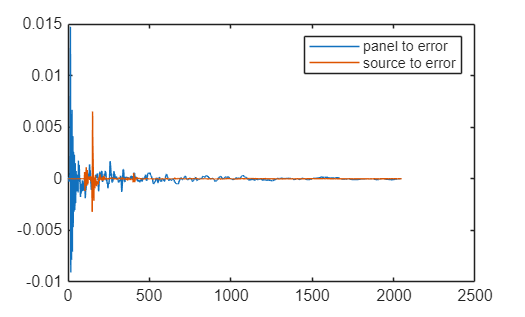

figure
plot(error_ir(start:cut))
% hold on
% plot(source_ir(start:cut))
hold on
plot(reverb_ir(start:cut))
legend('panel to error', 'source to error')

panel_ir = error_ir(start:cut);

[mics, fs] = audioread("double_mics.wav");
x_ref = mics(:, 2);
target = mics(:, 1);

filter_order = 8192;
n_iter = 10;

mean((x_ref - target).^2)

ans = 6.3028e-04

function results_plot(y, target, alg)
    figure
    plot(target)
    hold on
    plot(y)
    legend('ground truth', 'learned prediction')
    title(alg)
end

mu = 0.05;
eps = 1e-6;

[u_lms, w_lms, y_lms, mse_lms] = fxlms(x_ref, target, panel_ir, n_iter, filter_order, mu, eps);

iter: [1], mse: 1.6376e-07
iter: [2], mse: 1.4517e-07
iter: [3], mse: 1.3932e-07
iter: [4], mse: 1.3587e-07
iter: [5], mse: 1.3341e-07
iter: [6], mse: 1.3149e-07
iter: [7], mse: 1.2994e-07
iter: [8], mse: 1.2864e-07
iter: [9], mse: 1.2753e-07
iter: [10], mse: 1.2657e-07


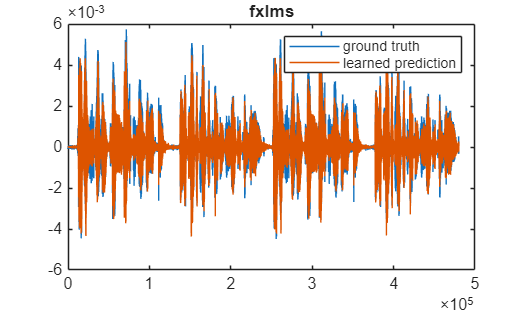

results_plot(y_lms, target, 'fxlms');

% lamda = .99999;
% delta = .001;
% 
% [u_rls, w_rls, y_rls, mse_rls] = fxrls(x_ref, target, panel_ir, n_iter, filter_order, lamda, delta);

% results_plot(y_lms, target, 'fxrls');

mu = 0.05;
eps = 1e-6;
block_len = 256;

[u_fdlms, w_fdlms, y_fdlms, mse_fdlms] = fd_fxlms(x_ref, target, panel_ir, n_iter, filter_order, mu, eps, block_len);

iter: [1], mse: 5.6689e-07
iter: [2], mse: 5.1291e-07
iter: [3], mse: 4.7184e-07
iter: [4], mse: 4.3961e-07
iter: [5], mse: 4.1372e-07
iter: [6], mse: 3.925e-07
iter: [7], mse: 3.7481e-07
iter: [8], mse: 3.5987e-07
iter: [9], mse: 3.4709e-07
iter: [10], mse: 3.3606e-07


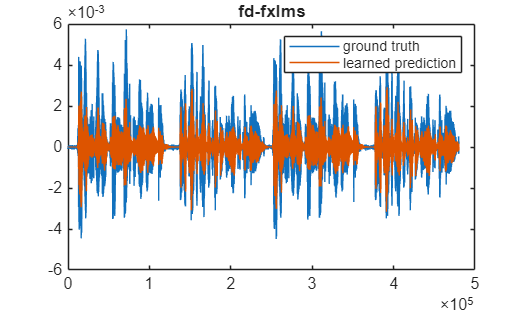

results_plot(y_fdlms, target, 'fd-fxlms');

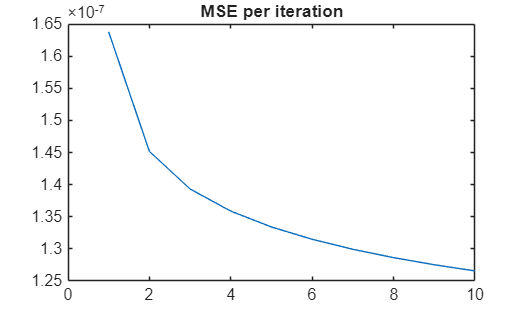

figure
plot(mse_lms)
% hold on
% plot(mse_fdlms)
% legend('fxlms', 'fd-fxlms')
title('MSE per iteration')

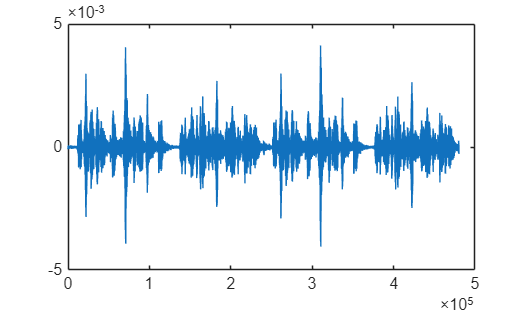

err = target - y_lms';
figure
plot(err)

soundsc(target, fs)

max_iter = 5;
fxlms_times = zeros(max_iter, 1);
fd_fxlms_times = zeros(max_iter, 1);

for i = 1:5
    tic
    [u_lms, w_lms, y_lms, mse_lms] = fxlms(x_ref, target, panel_ir, n_iter, filter_order, mu, eps);
    fxlms_times(i) = toc;
    
    tic
    [u_fdlms, w_fdlms, y_fdlms, mse_fdlms] = fd_fxlms(x_ref, target, panel_ir, n_iter, filter_order, mu, eps, block_len);
    fd_fxlms_times(i) = toc;
end

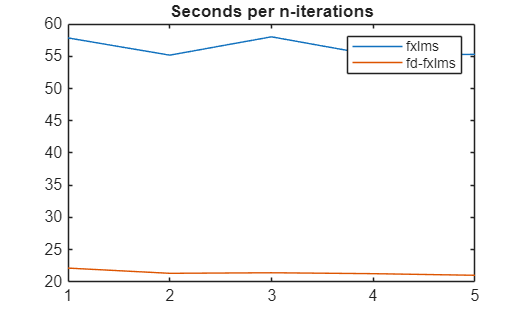

figure
plot(fxlms_times)
hold on
plot(fd_fxlms_times)
legend('fxlms', 'fd-fxlms')
title('Seconds per n-iterations')